# AlexNet을 사용한 "우유 판별" 전이 학습(Transfer Learning)

## 데이터 불러오기

clear, clc
%unzip('MerchData.zip');
imds = imageDatastore('우유','IncludeSubfolders',true,'LabelSource','foldernames');
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');    

#### 이미지 확인

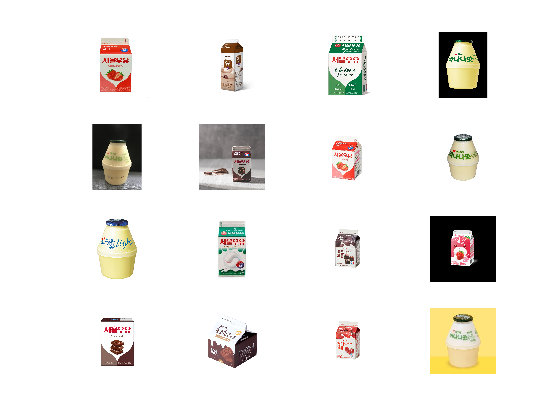

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

## 사전 훈련된 신경망 불러오기

net = alexnet;
%analyzeNetwork(net)

### 신경망 layer 확인

net.Layers

ans =   다음 계층을 포함한 25×1 Layer 배열:

     1   'data'     영상 입력         227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'    컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'    ReLU             ReLU
     4   'norm1'    교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'    최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'    그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'    ReLU             ReLU
     8   'norm2'    교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'    최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'    컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'    ReLU             ReLU
    12   'conv4'    그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'    ReLU             ReLU
    14   'conv5'    그룹화

inputSize = net.Layers(1).InputSize

inputSize =    227   227     3


### 마지막 계층 바꾸기

layersTransfer = net.Layers(1:end-3);

numClasses = numel(categories(imdsTrain.Labels))

numClasses = 4

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

### 신경망 훈련시키기

#### 훈련 이미지 데이터 증대

pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

#### 검증 이미지 데이터 증대

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

#### 네트워크 옵션

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

## 신경망 훈련

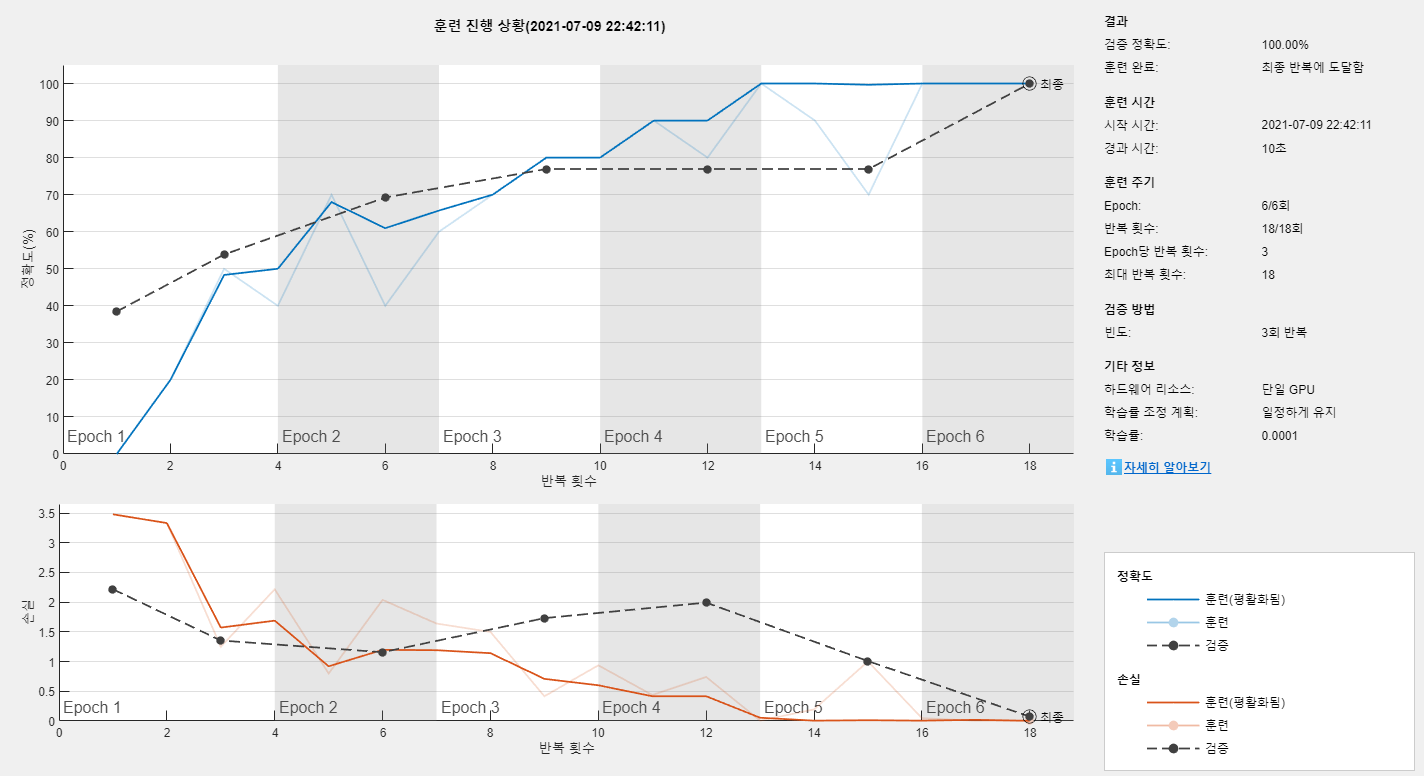

netTransfer = trainNetwork(augimdsTrain,layers,options);

신경망 저장

save("netTransfer.mat","netTransfer")

## 검증 영상 분류하기

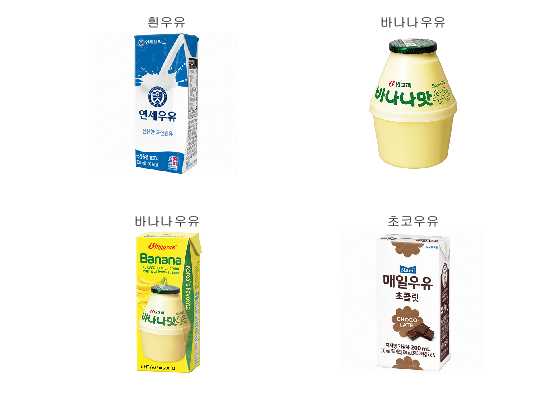

[YPred,scores] = classify(netTransfer,augimdsValidation);
idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label));
end

YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 1